%% Conversion des noms de couleurs (CSV) en colorcell

% fichier = "E:\Data\Aurelie\data\nocues\444119\220919_plane0\corcell_biapy_new.csv";   % chemin complet si le fichier n'est pas dans le dossier courant
fichier = "E:\Data\Aurelie\data\chroms\119\220923\registration\color_matched_biapy.csv";

% Correspondance nom -> code (modifiable ici)
nomsCouleurs = ["red"; "green"; "blue"; "yellow"; "magenta"; "cyan"; "black"];
codes        = [1;     2;       3;      4;        5;         6;      8];
% 7 : non attribué

% Lecture (la ligne d'en-tête "magenta" est prise en compte automatiquement)
T    = readtable(fichier, 'TextType', 'string');

noms = lower(strtrim(string(T{:,1})));
noms=noms(2:end,:);

nomsnew=noms(1:276);
nomsnew(277)='black';
nomsnew = [nomsnew; noms(277:end)];
noms=nomsnew;

% Conversion
[trouve, pos] = ismember(noms, nomsCouleurs);
if ~all(trouve)
    error('Couleur(s) non reconnue(s) : %s', ...
        strjoin(cellstr(unique(noms(~trouve))), ', '));
end
colorcell = codes(pos);              % colonne : une valeur par cellule, dans l'ordre du CSV

% Contrôles
fprintf('%d cellules converties\n', numel(colorcell));

305 cellules converties


for k = 1:numel(nomsCouleurs)
    fprintf('  %-8s -> %d : %d cellules\n', nomsCouleurs(k), codes(k), sum(colorcell == codes(k)));
end

  red      -> 1 : 81 cellules
  green    -> 2 : 13 cellules
  blue     -> 3 : 8 cellules
  yellow   -> 4 : 143 cellules
  magenta  -> 5 : 37 cellules
  cyan     -> 6 : 22 cellules
  black    -> 8 : 1 cellules


% assert(numel(colorcell) == NCell, 'colorcell ne correspond pas au nombre de cellules');

% Sauvegarde (optionnel)
% save('E:\Data\Aurelie\data\nocues\444119\220919_plane0\corcell_biapynew.mat', 'colorcell');
save('E:\Data\Aurelie\data\nocues\444119\220922_plane0\colorcell_biapynew.mat', 'colorcell');

305 cellules au total, 305 présentes dans les 2 fichiers.


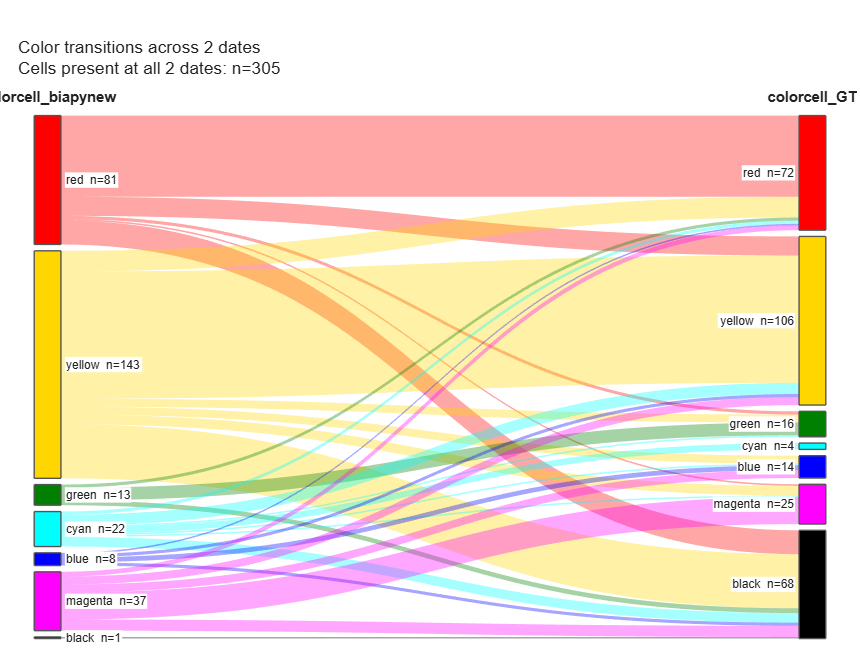

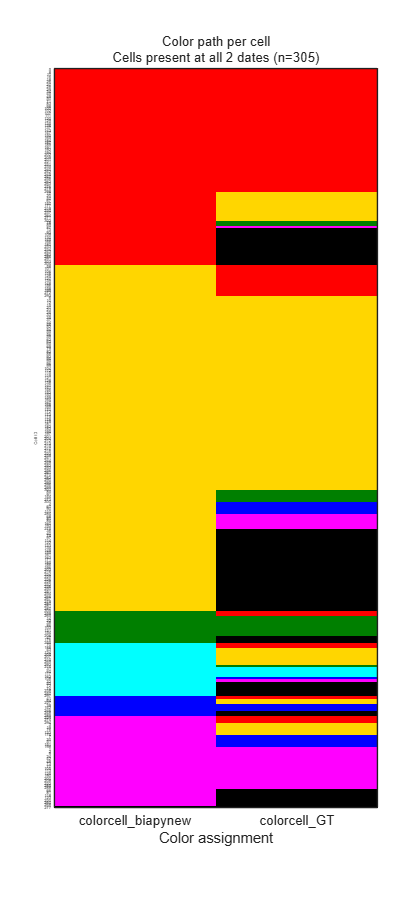

Écrit : E:\Data\Aurelie\analysis\Final\comparison_color\_sankey.png/.svg, E:\Data\Aurelie\analysis\Final\comparison_color\_paths.png, E:\Data\Aurelie\analysis\Final\comparison_color\_cells.csv, E:\Data\Aurelie\analysis\Final\comparison_color\_transitions.csv


% ou en donnant la liste
% files = {"E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcell_GT.mat"...
% %         ,"E:\Data\Aurelie\data\nocues\444119\220923_plane0\colorcell_GT.mat"};
% files = {"E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcell_GT.mat"...
%     ,"E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcell_Maxwell.mat",...
% %     "E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcellnew.mat"};
% files = {"E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcell_Maxwell.mat",...
%     "E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcell_GT.mat"};
% files = {"E:\Data\Aurelie\data\chroms\119\220919\registration\colorcellbiapyraw.mat",...
%     "E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcell_GT.mat"};
% files = {'E:\Data\Aurelie\data\nocues\444119\220919_plane0\corcell_biapynew.mat',...
%     "E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcell_GT.mat"};
% files = {'E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcellnew.mat',...
%     "E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcell_GT.mat"};
% files = {'E:\Data\Aurelie\data\nocues\444119\220923_plane0\corcell_biapynew.mat',...
%     "E:\Data\Aurelie\data\nocues\444119\220923_plane0\colorcell_GT.mat"};
% path1='E:\Data\Aurelie\data\nocues\444119\220923_plane0\corcell_biapynew.mat';
path1='E:\Data\Aurelie\data\nocues\444119\220922_plane0\colorcell_biapynew.mat';
path2="E:\Data\Aurelie\data\nocues\444119\220923_plane0\colorcell_GT.mat";


% path1="E:\Data\Aurelie\data\nocues\444175\221125_plane0\colorcellnew.mat";
% path2="E:\Data\Aurelie\data\nocues\444175\221125_plane0\colorcell_GT.mat";

% files = {"E:\Data\Aurelie\data\nocues\444175\221125_plane0\colorcellnew.mat",...
%     "E:\Data\Aurelie\data\nocues\444175\221125_plane0\colorcell_GT.mat"};
%"E:\Data\Aurelie\data\nocues\444175\221125_plane0\colorcell_Maxwellnew.mat"
%"E:\Data\Aurelie\data\nocues\444175\221125_plane0\colorcellnew.mat"
%"E:\Data\Aurelie\data\nocues\444175\221125_plane0\colorcell_GT.mat"

% files = {"E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcell_Maxwell.mat",...
%     "E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcell_GT.mat"...
%     ,"E:\Data\Aurelie\data\chroms\119\220919\registration\colorcellbiapyraw.mat"};
files = {path1,path2};
colorcell_sankey(files, 'Out', "E:\Data\Aurelie\analysis\Final\comparison_color\")

Accord global : 53.8% (305 neurones)
Accord sur les neurones colorés par les deux méthodes : 68.8% (237 neurones)
Accord sur les neurones colorés selon GT : 68.8% (237 neurones, dont 0 noirs pour biapynew)


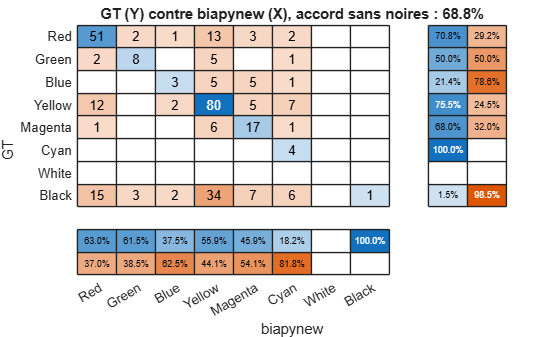


% avec une colonne ex vivo
% colorcell_sankey(files4, 'Labels', {'Ex vivo','220919','220922','220923'})
% color = load("E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcell_Maxwell.mat");
% colorcell_invivo = color.colorcell;
% color = load("E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcell_GT.mat");
color = load(path2);
colorcell_GT = color.colorcell;
% color = load('E:\Data\Aurelie\data\nocues\444119\220919_plane0\corcell_biapynew.mat');
color = load(path1);
colorcell_biapy = color.colorcell;
% color = load ("E:\Data\Aurelie\data\chroms\119\220919\registration\colorcellbiapyraw.mat");
% colorcell_biapyold = color.colorcell;
% colorcell_method1 = uint8(colorcell_invivo);
% colorcell_method2 = uint8(colorcell_exvivo);
% disp ("Matrice de contingence colorcell Aure vs GT exvivo")
% confusion_matrix (colorcell_GT,colorcell_invivo,'GT','invivo');%method1reference , method 2
confusion_matrix (colorcell_GT,colorcell_biapy,'GT','biapynew');

% confusion_matrix (colorcell_GT,colorcell_biapyold,'GT','biapyold');

%%444119\220923_plane0

files = {"E:\Data\Aurelie\data\nocues\444119\220923_plane0\colorcell_Maxwell260610.mat",...
    "E:\Data\Aurelie\data\chroms\119\220923\registration\color_matched_biapyJC_26_06_10.mat"};
% 
% colorcell_sankey(files, 'Out', "E:\Data\Aurelie\analysis\Final\comparison_color\")

% files = {"E:\Data\Aurelie\data\chroms\119\220923\registration\colorcell_biapy_raw.mat",...
%     "E:\Data\Aurelie\data\chroms\119\220923\registration\color_matched_biapyJC_26_06_10.mat"};

colorcell_sankey(files, 'Out', "E:\Data\Aurelie\analysis\Final\comparison_color\")
% 
color = load("E:\Data\Aurelie\data\nocues\444119\220923_plane0\colorcell_Maxwell260610.mat");
colorcell_invivo = color.colorcell_classification;
% colorcell_invivo = load("E:\Data\Aurelie\data\nocues\444119\220923_plane0\colorcell_Maxwell260610.mat");
color = load("E:\Data\Aurelie\data\chroms\119\220923\registration\color_matched_biapyJC_26_06_10.mat");
colorcell_GT = color.colorcell;
color = load("E:\Data\Aurelie\data\chroms\119\220923\registration\colorcell_biapy_raw.mat");
colorcell_biapy = color.colorcell;
% colorcell_method1 = uint8(colorcell_invivo);
% colorcell_method2 = uint8(colorcell_exvivo);
% disp ("Matrice de contingence colorcell Aure vs GT exvivo")
confusion_matrix (colorcell_invivo,colorcell_GT);
% confusion_matrix (colorcell_biapy,colorcell_GT);
confusion_matrix (colorcell_invivo,colorcell_GT);

%%444175\221125_plane0

files = {"E:\Data\Aurelie\data\nocues\444175\221125_plane0\colorcell_Maxwellnew.mat",...
    "E:\Data\Aurelie\data\nocues\444175\221125_plane0\colorcell_GT.mat"};

colorcell_sankey(files, 'Out', "E:\Data\Aurelie\analysis\Final\comparison_color\")
% 
% files = {"E:\Data\Aurelie\data\nocues\444119\220923_plane0\colorcell_Maxwell.mat",...
%     "E:\Data\Aurelie\data\nocues\444119\220923_plane0\colorcell_GT.mat"};
% 
% colorcell_sankey(files, 'Out', "E:\Data\Aurelie\analysis\Final\comparison_color\")

% color = load("E:\Data\Aurelie\data\nocues\444175\221125_plane0\colorcell_Maxwellnew.mat");
% colorcell_invivo = color.colorcell;
color = load("E:\Data\Aurelie\data\nocues\444175\221125_plane0\colorcell_GT.mat");
colorcell_GT = color.colorcell;
% color = load("E:\Data\Aurelie\data\chroms\119\220919\registration\colorcellbiapyraw.mat");
% colorcell_biapy = color.colorcell;
% colorcell_method1 = uint8(colorcell_invivo);
% colorcell_method2 = uint8(colorcell_exvivo);
% disp ("Matrice de contingence colorcell Aure vs GT exvivo")
% confusion_matrix (colorcell_invivo,colorcell_GT);
% confusion_matrix (colorcell_biapy,colorcell_GT);